Sam Kramer 

Dr. Alfred Wicks

ME 5714: Digital Signal Processing

## Assignment 5 -- Correlation Functions

%{
    This will be a script that will solve the problems in Assignment 5.
    This will be used to explore the behavior of correlation functions.

    Sam Kramer
    Feb 8th, 2023
%}

% --Script setup
    clear; clc; close all; format compact;

    Assignment 5:

Direct from the "Hunt for Red October" is the sonar signal requested by the Russian Capt. 

Your task is to find the range of the other submarine.

The data vector named 'hpdata' is from the hydrophone on the red october. the ping is also provided as the vector 'ping'.

- Use the autocorrelation to attempt to estimate the range. Write our own code, and compare to xcorr().

- Cross-correlate the 'ping' signal with the 'hpdata' signal. Write your own code and compare to xcorr(). 

- What is the range of the other submarine?

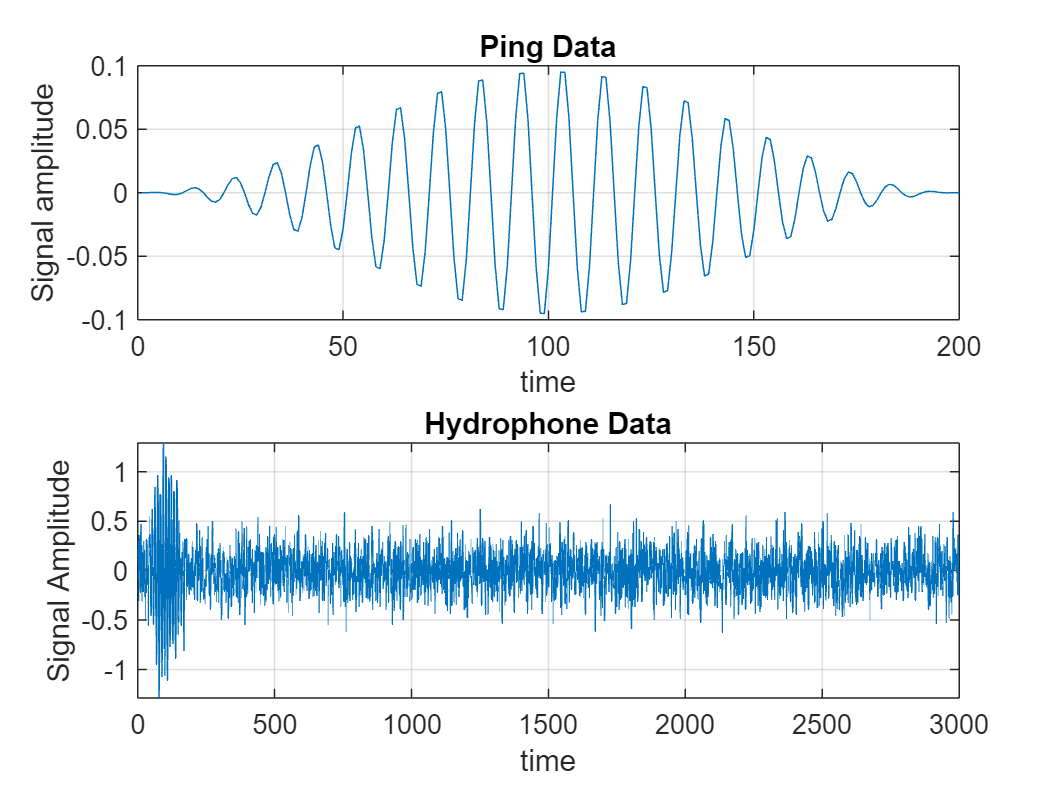

% --Load in the data from the folder
    data = load("A5_data.mat");
    
% --Reformat data structure to different vectors 
    hpdata = data.hpdata;
    ping = data.ping;
    
% --Plot the hydrophone data
    subplot(2,1,2)
    plot(hpdata);
        hold on
        grid on
        title('Hydrophone Data')
        xlabel('time')
        ylabel('Signal Amplitude') 
        
% --Plot the ping data
    subplot(2,1,1)
        plot(ping)
        hold on 
        grid on
        title('Ping Data')
        xlabel('time')
        ylabel('Signal amplitude')                

## Using Matlab Provided Functions

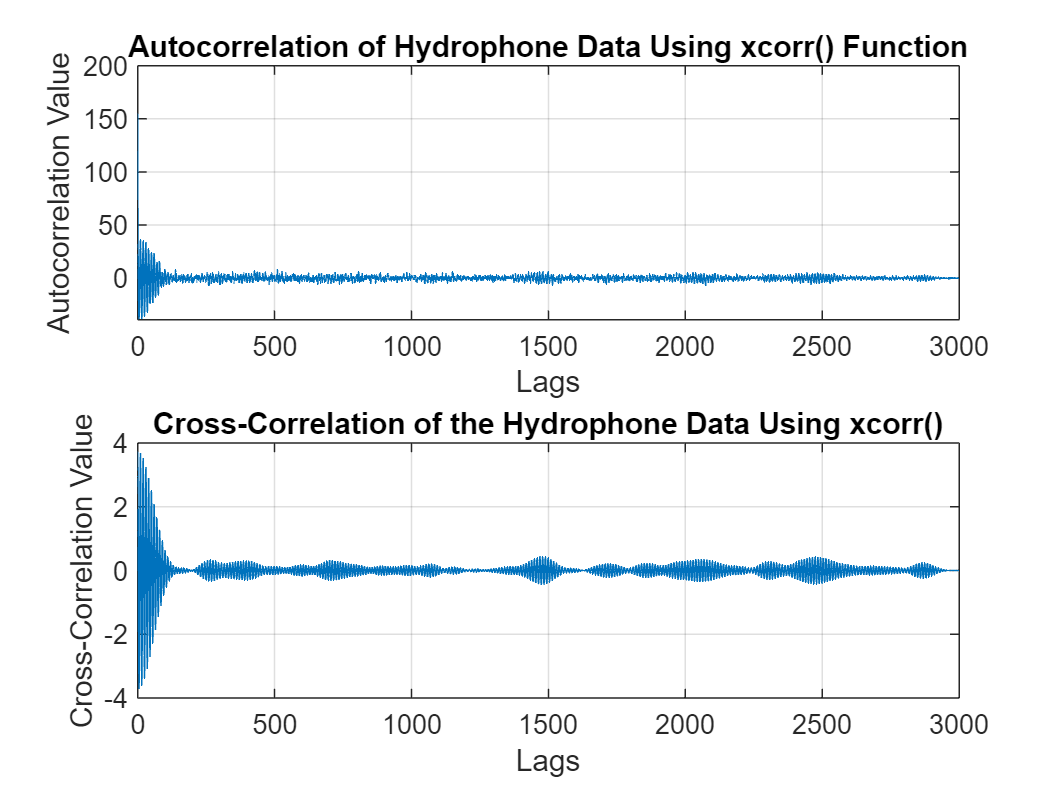

% --Autocorrelation from xcorr() function from matlab
    C = xcorr(hpdata);
    M = length(hpdata);
    lags = -M+1:M-1;
    
% --Plot data
    figure(2)
    subplot(2,1,1)
    plot(lags,C)
    
    % --Format plot
        hold on
        grid on
        title('Autocorrelation of Hydrophone Data Using xcorr() Function')
        xlabel('Lags')
        ylabel('Autocorrelation Value')
        xlim([0 3000])
        
% --Cross Correlation from xcorr() function 
    C = xcorr(hpdata,ping);
    
% --Plot data
    subplot(2,1,2)
    plot(lags,C)
    
    % --Format plot
        hold on
        grid on
        title('Cross-Correlation of the Hydrophone Data Using xcorr()')
        xlabel('Lags')
        ylabel('Cross-Correlation Value')
        xlim([0 3000])

## Using My Own Functions

% --Call on my own Auto correlation function
    value = autocorrelation1(hpdata);

% --Plot autocorrelation values
    figure(3)
    subplot(2,1,1)
    plot(value)
        grid on
        hold on
        ylabel('Autocorrelation Values')
        title('Autocorrelations Using My Own Function');
        subtitle('Non-Normalized');
        
% --Call on autocorrelation function 2 (Dividing by number of samples)
    value = autocorrelation2(hpdata);
       
% --Plot values
    subplot(2,1,2)
    plot(value)
        grid on
        hold on
        xlabel('Lags')
        ylabel('Autocorrelation Values')
        subtitle('Normalized');
        

% --Call on my own Cross-Correlation Function
    value = crosscorrelation1(hpdata,ping);
    
% --Plot data
    figure(4)
    subplot(2,1,1)
    plot(value)
        hold on
        grid on
        ylabel('Cross-Correlation values')
        subtitle('Non-normalized')
        title('Cross-Correlations Using my Own Functions')
        
% --Call on my own Cross-Correlation Function
    value = crosscorrelation2(hpdata,ping);
    
% --Plot data
    subplot(2,1,2)
    plot(value)
        hold on
        grid on
        ylabel('Cross-Correlation values')
        subtitle('Normalized')
        xlabel('Lags')
        

## Analysis of Data

    Through this assignment I noticed there were two different ways of doing the correlations when we were doing it by ourselves. There was the normalized way which divided by the amount of samples in the summation, and then there was the non-normalized way which is what MATLAB functions used. As a result I made functions for both to compare the data. The non-normalized functions have less noise towards the higher lags. I made both to confirm that my functions matched the MATLAB functions, which they do. 

###     How far away is the opposition submarine?

    If we look at the data, there is a ping spike at around 1500 lags. Meaning that the submarine would be roughly 750 lags ahead, because the sound must bounce back. That can be found into a distance through the formula:


$$d=\;\frac{\tau *C}{2*f_s }$$
 

    Where C is the speed of sound in water, tau is the amount of lags and Fs is the sample frequency. This will give the distance of the enemy submarine. If we say that the sample frequency of the sonar system is 10,000 Hz and C = 1480 m/s, then the distance of the submarine will be 110 meters away.

## Functions definitions

function value = autocorrelation1(data)
%{
    This is the function that is used to calculate the autocorrelation for
    the given data set that is input. This will output a length N vector if
    data is a 1xN data vector. 
%}

% --Function Setup
    N = length(data);
    value = [];
    
% --For loop
    for tau = 1:N-1
        
        % --Calculate Rxx at that tau
            Rxx = (N-(tau-1))*mean(data(1:(N-(tau-1))) .* data(tau:N));
            value = [value Rxx];
                
    end % loop end

    
end % Function end



function value = autocorrelation2(data)
%{
    This is the function that is used to calculate the autocorrelation for
    the given data set that is input. This will output a length N vector if
    data is a 1xN data vector. 
%}

% --Function Setup
    N = length(data);
    value = [];
    
% --For loop
    for tau = 1:N-1
        
        % --Calculate Rxx at that tau
            Rxx = mean(data(1:(N-(tau-1))) .* data(tau:N));
            value = [value Rxx];
                
    end % loop end

    
end % Function end



function value = crosscorrelation1(data1, data2)
%{
    
%}

% --Function Setup
    N = length(data1);
    M = length(data2);
    value = [];
    append = zeros(1, N - M);
    data2 = [data2 append];
    
%--For loop
    for tau = 1:N-1
        
        % --Calculate Rxy at that tau
        Rxy = mean(data1(tau:N) * data2(1:N - (tau-1))');
        value = [value Rxy];
        
        
    end % loop end

end % Function end



function value = crosscorrelation2(data1, data2)
%{
    
%}

% --Function Setup
    N = length(data1);
    M = length(data2);
    value = [];
    append = zeros(1, N - M);
    data2 = [data2 append];
    
%--For loop
    for tau = 1:N-1
        
        % --Calculate Rxy at that tau
        Rxy = mean(data1(tau:N) .* data2(1:N - (tau-1)));
        value = [value Rxy];
        
    end % loop end

end % Function end
